Definicja rozważanej transmitancji $G(s) = \frac{L(s)}{s^{k}M(s)}$:

sys = tf([1 -2 1], [1 3 1 1]);

Sprawdzenie czy są spełnione warunki stosowalności kryterium Nyquista:

% Pobranie współczynników licznika i mianownika
[num_coeffs, den_coeffs] = tfdata(sys, "v");

% 1. Stopień licznika i mianownika
deg_num_total = length(num_coeffs) - find(num_coeffs ~= 0, 1); 
deg_den_total = length(den_coeffs) - find(den_coeffs ~= 0, 1);

deg_correct = deg_den_total > deg_num_total;

% 2. Stopień astatyzmu (k)
% Liczymy ile zer znajduje się na końcu wektora współczynników mianownika
k = 0;
for i = length(den_coeffs):-1:1
    if den_coeffs(i) == 0
        k = k + 1;
    else
        break;
    end
end

% Wyodrębnienie wielomianu M(s) (mianownik bez s^k)
M_coeffs = den_coeffs(1:end-k);

% 3. Czy L(s) i M(s) są względnie pierwsze?
num_zeros = roots(sys.Numerator{1});
den_zeros = roots(M_coeffs);

is_coprime = true;
for index = 1:length(num_zeros)
    if ~isempty(find(den_zeros == num_zeros(index), 1))
        is_coprime = false;
    end
end

% 4. Czy L(0) / M(0) ~= 0?
L_0 = num_coeffs(end);
M_0 = M_coeffs(end);
ratio_not_zero = (L_0 / M_0) ~= 0;

Sprawdzamy czy można zastosować kryterium Nyquista:

if deg_correct && is_coprime && ratio_not_zero
    disp("Można zastosować kryterim Nyquista");
else
    disp("Warunki stosowalności kryterium Nyquista nie są spełnione.");
    return;
end

Można zastosować kryterim Nyquista


Plot musi okrążać punkt (-1, 0) dokładnie:

m = sum(den_zeros > 0);
fprintf("%d razy", m);

0 razy

Wyrysowanie plotu Nyquista:

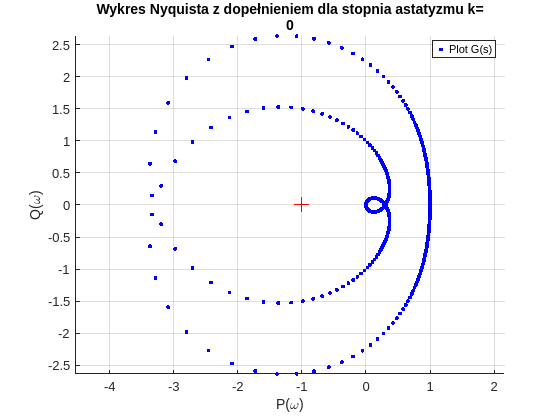

wh = logspace(-5, 5, 1000);
w = [-flip(wh), wh];
[p, q, w] = nyquist(sys, w);
p = squeeze(p);
q = squeeze(q);

figure();
grid on;
hold on;
axis equal;
xlabel("P(\omega)");
ylabel("Q(\omega)");
legend("Location", "best");
title(["Wykres Nyquista z dopełnieniem dla stopnia astatyzmu k=", num2str(k)]);
plot(p, q, "b", "LineWidth", 2, "DisplayName", "Plot G(s)", "LineStyle", "none", "Marker", ".");
plot(-1, 0, "r+", "MarkerSize", 10, "HandleVisibility", "off");


% --- LOGIKA DOPEŁNIENIA ---
if k > 0
    % Wyznaczamy promień dopełnienia
    R_plot = max(q);
    
    % Kąty dla dopełnienia: od końca ujemnej częstotliwości do początku dodatniej
    % Dla jednej całki to 180 stopni, dla dwóch 360 itd.
    if L_0 / M_0 > 0
        phi_start = k * pi/2;
        phi_end = -k * pi/2;
    else
        phi_start = k * pi/2 - pi;
        phi_end = -k * pi/2 - pi;
    end
    phi = linspace(phi_start, phi_end, 100);
    
    % Współrzędne łuku
    p_arc = 1.2*(max(p) - min(p)) * cos(phi) + max(p);
    q_arc = R_plot * sin(phi);
end

% --- RYSOWANIE ---
% 2. Dopełnienie (jeśli istnieje)
if k > 0
    plot(p_arc, q_arc, "r--", "LineWidth", 1.5, "DisplayName", "Dopełnienie (\infty)");
    
    % Dodanie strzałek kierunkowych na łuku
    mid = round(length(p_arc)/2);
    quiver(p_arc(mid), q_arc(mid), p_arc(mid+1)-p_arc(mid), q_arc(mid+1)-q_arc(mid), ...
           5, "r", "LineWidth", 2, "MaxHeadSize", 10, "HandleVisibility", "off");
end

Symulacja układu z zamknięta petlą sprzężenia zwrotnego:

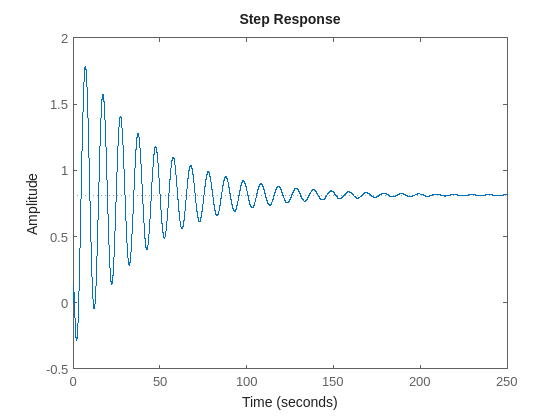

K = 0.23;
Gz = feedback(sys, K);
figure();
step(Gz);

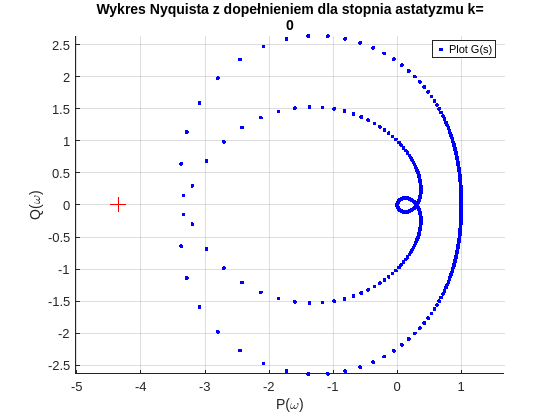


figure();
grid on;
hold on;
axis equal;
xlabel("P(\omega)");
ylabel("Q(\omega)");
legend("Location", "best");
title(["Wykres Nyquista z dopełnieniem dla stopnia astatyzmu k=", num2str(k)]);
plot(p, q, "b", "LineWidth", 2, "DisplayName", "Plot G(s)", "LineStyle", "none", "Marker", ".");
plot(-1/K, 0, "r+", "MarkerSize", 10, "HandleVisibility", "off");